Paraméterek beállítása

Meg kell adni a beolvasás adatait.

- time_point: hány időpillanatban mértünk

- sample_num: hány minta volt

- torzsszam: különböző törzsek száma (backgroundot is bele kell számolni!)

- OD_table: a tecan kimeneti fájljában hol helyezkedik el az OD adat

- GFP_table: a tecan kimeneti fájljában hol helyezkedik el a GFP adat

- mCh_table: a tecan kimeneti fájljában hol helyezkedik el az mCh adat

- layout: csatolt layout mintájára, well-ek leírása, hogy pontosan mi van bennük

- inputname: Tecan kimeneti excel fájljának a neve, amiben az adatok vannak

Ha valamelyik oszlopot nem szeretnénk figyelembe venni, akkor a layout fájlban a sorszámot át kell írni a legmagasabb sorszám+1-re. pl.: 18 törzs+ 0. background=19 a törzsszám, így 19-re kell átírni a kivenni kívánt well sorszámát.

clc;
clear;
time_point=52;
sample_num=96;
torzsszam=19;
measurement_num=1;
OD_table='A93:CU145';
GFP_table='A203:CU255';
mCh_table='A148:CU200';
layout='layout_dipl_jav.xlsx';
inputname='Yeast_ON(Modified)_20210217_141618_diploid.xlsx'; %értékeket tartalmazó fájl
%kivetel=[]; %amelyik oszlopokat nem szeretnénk figyelembe venni

Adatok beolvasása

OD: d_OD-ban lesznek az OD adatok, time_points_OD-ban az időpillanatok, temperatures_OD-ban a hőmérséklet (nem használjuk fel, csak adat szempontjából fontos)

d_OD=nan(time_point,sample_num,measurement_num);
time_points_OD=nan(time_point,measurement_num);
temperatures_OD=nan(time_point,measurement_num);
for i=1:measurement_num
    i;
    [data,txt,raw]=xlsread(inputname,i,OD_table); %a fájl adott része
    s=size(data);
    d_OD(1:s(1),1:s(2)-2,i)=data(:,3:end);
    time_points_OD(1:s(1),i)=data(:,1);
    temperatures_OD(1:s(1),i)=data(:,2);
end

GFP

d_GFP=nan(time_point,sample_num,measurement_num);
time_points_GFP=nan(time_point,measurement_num);
temperatures_GFP=nan(time_point,measurement_num);
for i=1:measurement_num
    i;
[data,txt,raw]=xlsread(inputname,i, GFP_table); %a fájl adott része
s=size(data);
d_GFP(1:s(1),1:s(2)-2,i)=data(:,3:end);
time_points_GFP(1:s(1),i)=data(:,1);
temperatures_GFP(1:s(1),i)=data(:,2);
end

mCh

d_mCh=nan(time_point,sample_num,measurement_num);
time_points_mCh=nan(time_point,measurement_num);
temperatures_mCh=nan(time_point,measurement_num);
for i=1:measurement_num
    i;
[data,txt,raw]=xlsread(inputname,i, mCh_table); %a fájl adott része
s=size(data);
d_mCh(1:s(1),1:s(2)-2,i)=data(:,3:end);
time_points_mCh(1:s(1),i)=data(:,1);
temperatures_mCh(1:s(1),i)=data(:,2);
end

Plate layout: layout fájl beolvasása, különböző változókba elmentjük az adatokat. Ebből lényegében csak a sorszámot, a well nevét és a well azonosítóját (pl.:A10) használjuk a későbbiekben még.

[data,txt,raw]=xlsread(layout,1);
well=txt(2:end,1);
strain=txt(2:end,3);
position=txt(2:end,4);
corner=ismember(position,'corner');
edge=ismember(position,'edge');
inner=ismember(position,'inner');
sorszam=data(:,1);
sorszam2=nan(size(sorszam,1),max(sorszam)+1); 
for i=0:max(sorszam)
sorszam2(:,i+1)=sorszam==i;
end
strain_no=data(:,4);
strain0=(strain_no==0);
strain1=(strain_no==1);
strain2=(strain_no==2);
W303=data(:,5);
Y55=data(:,6);
a=[data(:,7), data(:,7), data(:,7), data(:,7), ones(size(data(:,7)))];
alpha=[data(:,8), data(:,8), data(:,8), data(:,8), zeros(size(data(:,8)))];
KanMx=data(:,9);
GFP=data(:,10);
mCh=data(:,11);

Kimentés excelbe: xxx_group fájlba kimenti a csoportosított adatsorokat. Minden törzset más munkalapra tesz, A H oszlopban kerülnek az átlagok, I oszlopba pedig a relatív szórás. A végén ha van kivett oszlop, akkor azok kerülnek az utolsó munkalapra.

filename='OD_group.xlsx';
%d_OD(:,kivetel)=NaN;
data_sum=d_OD;
sample=0:torzsszam;
torzsek_nevei=[];
for i=sample
    if i<torzsszam
        sheet=char(unique(strain(sorszam==i)));
        torzsek_nevei=[torzsek_nevei convertCharsToStrings(sheet)];
        data_sum_act=data_sum(:,sorszam==i,:);
        data=reshape(data_sum_act,size(data_sum_act,1),size(data_sum_act,2)*size(data_sum_act,3));
        well_act=repmat(well(sorszam==i),size(data_sum_act,3),1)';
        measuremet_act=reshape(repmat({'m1'},length(well(sorszam==i)),1),1,length(well(sorszam==i))*size(data_sum_act,3));
        xlswrite(filename,measuremet_act,sheet,'A1');
        xlswrite(filename,well_act,sheet,'A2');
        xlswrite(filename,data,sheet,'A3');
        avg=(mean(data','omitnan'))';
        szoras=avg./((std(data','omitnan'))');
        xlswrite(filename,{'atlag'},sheet,'H2');
        xlswrite(filename,{'szoras'},sheet,'I2');
        xlswrite(filename,avg,sheet,'H3');
        xlswrite(filename,szoras,sheet,'I3');
    else
        sheet="kivett oszlopok";
        data_sum_act=data_sum(:,sorszam==i,:);
        data=reshape(data_sum_act,size(data_sum_act,1),size(data_sum_act,2)*size(data_sum_act,3));
        well_act=repmat(well(sorszam==i),size(data_sum_act,3),1)';
        measuremet_act=reshape(repmat({'m1'},length(well(sorszam==i)),1),1,length(well(sorszam==i))*size(data_sum_act,3));
        xlswrite(filename,measuremet_act,sheet,'A1');
        xlswrite(filename,well_act,sheet,'A2');
        xlswrite(filename,data,sheet,'A3');
    end
end

GFP

filename='GFP_group.xlsx';
%d_GFP(:,kivetel)=NaN;
data_sum=d_GFP;
sample=0:torzsszam;
for i=sample
    if i<torzsszam
        sheet=char(unique(strain(sorszam==i)));
        data_sum_act=data_sum(:,sorszam==i,:);
        data=reshape(data_sum_act,size(data_sum_act,1),size(data_sum_act,2)*size(data_sum_act,3));
        well_act=repmat(well(sorszam==i),size(data_sum_act,3),1)';
        measuremet_act=reshape(repmat({'m1'},length(well(sorszam==i)),1),1,length(well(sorszam==i))*size(data_sum_act,3));
        xlswrite(filename,measuremet_act,sheet,'A1');
        xlswrite(filename,well_act,sheet,'A2');
        xlswrite(filename,data,sheet,'A3');
        avg=(mean(data','omitnan'))';
        szoras=avg./((std(data','omitnan'))');
        xlswrite(filename,{'atlag'},sheet,'H2');
        xlswrite(filename,{'szoras'},sheet,'I2');
        xlswrite(filename,avg,sheet,'H3');
        xlswrite(filename,szoras,sheet,'I3');
    else
        sheet="kivett oszlopok";
        data_sum_act=data_sum(:,sorszam==i,:);
        data=reshape(data_sum_act,size(data_sum_act,1),size(data_sum_act,2)*size(data_sum_act,3));
        well_act=repmat(well(sorszam==i),size(data_sum_act,3),1)';
        measuremet_act=reshape(repmat({'m1'},length(well(sorszam==i)),1),1,length(well(sorszam==i))*size(data_sum_act,3));
        xlswrite(filename,measuremet_act,sheet,'A1');
        xlswrite(filename,well_act,sheet,'A2');
        xlswrite(filename,data,sheet,'A3');
    end
end

mCh

filename='mCh_group.xlsx';
%d_mCh(:,kivetel)=NaN;
data_sum=d_mCh;
sample=0:torzsszam;
for i=sample
     if i<torzsszam
        sheet=char(unique(strain(sorszam==i)));
        data_sum_act=data_sum(:,sorszam==i,:);
        data=reshape(data_sum_act,size(data_sum_act,1),size(data_sum_act,2)*size(data_sum_act,3));
        well_act=repmat(well(sorszam==i),size(data_sum_act,3),1)';
        measuremet_act=reshape(repmat({'m1'},length(well(sorszam==i)),1),1,length(well(sorszam==i))*size(data_sum_act,3));
        xlswrite(filename,measuremet_act,sheet,'A1');
        xlswrite(filename,well_act,sheet,'A2');
        xlswrite(filename,data,sheet,'A3');
        avg=(mean(data','omitnan'))';
        szoras=avg./((std(data','omitnan'))');
        xlswrite(filename,{'atlag'},sheet,'H2');
        xlswrite(filename,{'szoras'},sheet,'I2');
        xlswrite(filename,avg,sheet,'H3');
        xlswrite(filename,szoras,sheet,'I3');
     else
        sheet="kivett oszlopok";
        data_sum_act=data_sum(:,sorszam==i,:);
        data=reshape(data_sum_act,size(data_sum_act,1),size(data_sum_act,2)*size(data_sum_act,3));
        well_act=repmat(well(sorszam==i),size(data_sum_act,3),1)';
        measuremet_act=reshape(repmat({'m1'},length(well(sorszam==i)),1),1,length(well(sorszam==i))*size(data_sum_act,3));
        xlswrite(filename,measuremet_act,sheet,'A1');
        xlswrite(filename,well_act,sheet,'A2');
        xlswrite(filename,data,sheet,'A3');
    end
end

Az egyes telep típusok görbéi együtt, átlagos görbéik (Od, GFP, mCh)

Itt kapjuk meg a csoportosítoptt és átlagolt görbéket. Szükséges leellenőrizni, hogy minden well-be a megfelelő törzs került-e. Amennyiben kicsik a szórások, akkor nem szükséges well adatot kivenni a további vizsgálatokból. Amennyiben nagy a szórás 1 adatsor miatt, akkor a kód elején olvasható módon ki lehet venni az adatot, ami a későbbiekben nem vesz részt az adatok összegzésénél.

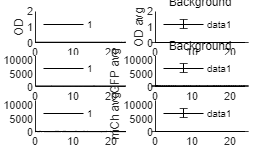

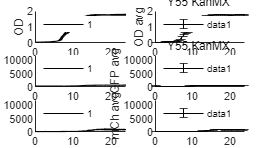

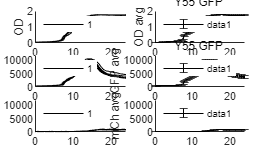

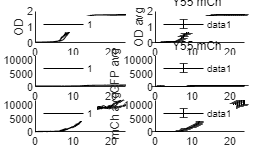

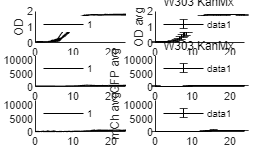

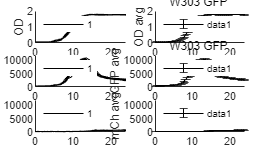

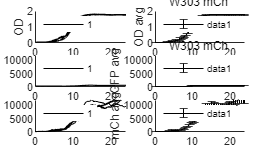

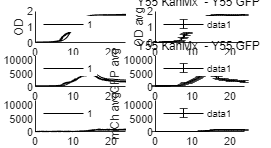

plot_color={'k-', 'b-', 'g-', 'r-', 'm-'}; %1,2,3,4,5 measurement , ha több mérés van
plot_name={'OD', 'GFP', 'mCh'};
meres=1;
%plot_cat=0:18;
plot_cat=2;

for plot_cat=0:18
figure('units','normalized','outerposition',[0 0 1 1])

OD ábrázolása

plot_data=d_OD;
time_points=time_points_OD;
plot_name_act=plot_name{1};

subtitle(convertCharsToStrings(unique(strain(sorszam==plot_cat))));
p_avg=nan(size(time_points,1), size(meres,2));
p_std=p_avg;

subplot(3,2,1);
set(gca,'FontSize',8)
hold on;
for m=meres
    p=plot_data(:,sorszam==plot_cat,m);  
    plot(time_points(:,m)/(60*60), p, plot_color{m});
    p_avg(:,m)=mean(p,2,'omitnan');
    p_std(:,m)=std(p,[],2,'omitnan');
end
ylabel(plot_name_act);
xlim([0 24]);
ylim([0 2]);
xlabel('time(h)');

for m=meres
    p=plot_data(:,sorszam==plot_cat,m);  
    p2(m)=plot(time_points(:,m)/(60*60), p(:,1,:), plot_color{m}, 'Display', num2str(m));
end
legend(p2);
legend('Location', 'northwest');
legend('boxoff');

subplot(3,2,2);
set(gca,'FontSize',8)
hold on;
for m=meres
    errorbar(time_points(:,m)/(60*60), p_avg(:,m), p_std(:,m), plot_color{m})
end
ylabel([plot_name_act, ' avg']);
xlim([0 24]);
ylim([0 2]);
xlabel('time(h)');
legend(p2);
legend('Location', 'northwest');
legend('boxoff');


GFP ábrázolása

plot_data=d_GFP;
time_points=time_points_GFP;
plot_name_act=plot_name{2};

subtitle(convertCharsToStrings(unique(strain(sorszam==plot_cat))));
p_avg=nan(size(time_points,1), size(meres,2));
p_std=p_avg;

subplot(3,2,3);
set(gca,'FontSize',8)
hold on;
for m=meres
    p=plot_data(:,sorszam==plot_cat,m);  
    plot(time_points(:,m)/(60*60), p, plot_color{m});
    p_avg(:,m)=mean(p,2,'omitnan');
    p_std(:,m)=std(p,[],2,'omitnan');
end
ylabel(plot_name_act);
xlim([0 24]);
ylim([0 12000]);
xlabel('time(h)');

for m=meres
    p=plot_data(:,sorszam==plot_cat,m);  
    p2(m)=plot(time_points(:,m)/(60*60), p(:,1,:), plot_color{m}, 'Display', num2str(m));
end
legend(p2);
legend('Location', 'northwest');
legend('boxoff');

subplot(3,2,4);
set(gca,'FontSize',8)
hold on;
for m=meres
    errorbar(time_points(:,m)/(60*60), p_avg(:,m), p_std(:,m), plot_color{m})
end
ylabel([plot_name_act, ' avg']);
xlim([0 24]);
ylim([0 12000]);
xlabel('time(h)');
legend(p2);
legend('Location', 'northwest');
legend('boxoff');

mCh ábrázolása

plot_data=d_mCh;
time_points=time_points_mCh;
plot_name_act=plot_name{3};

subtitle(convertCharsToStrings(unique(strain(sorszam==plot_cat))));
p_avg=nan(size(time_points,1), size(meres,2));
p_std=p_avg;

subplot(3,2,5);
set(gca,'FontSize',8)
hold on;
stat_mCh=nan(size(time_points,1), torzsszam*2);
for m=meres
    p=plot_data(:,sorszam==plot_cat,m);  
    plot(time_points(:,m)/(60*60), p, plot_color{m});
    p_avg(:,m)=mean(p,2,'omitnan');
    p_std(:,m)=std(p,[],2,'omitnan');
end
ylabel(plot_name_act);
xlim([0 24]);
ylim([0 12000]);
xlabel('time(h)');

for m=meres
    p=plot_data(:,sorszam==plot_cat,m);  
    p2(m)=plot(time_points(:,m)/(60*60), p(:,1,:), plot_color{m}, 'Display', num2str(m));
end
legend(p2);
legend('Location', 'northwest');
legend('boxoff');

subplot(3,2,6);
set(gca,'FontSize',8)
hold on;
for m=meres
    errorbar(time_points(:,m)/(60*60), p_avg(:,m), p_std(:,m), plot_color{m})
end
ylabel([plot_name_act, ' avg']);
xlim([0 24]);
ylim([0 12000]);
xlabel('time(h)');
legend(p2);
legend('Location', 'northwest');
legend('boxoff');

saveas(gcf,[char(unique(strain(sorszam==plot_cat))), '.jpg']);
end

Adattranszformálás kezdete

Átlagolt görbék beolvasása, kimentése

format bank;
header=unique(strain)';
osszesitett_matrix_OD=nan(size(time_points,1), torzsszam);
for i=1:19
    [data,txt,raw]=xlsread("OD_group.xlsx",torzsek_nevei(i),'H3:H55');
    osszesitett_matrix_OD(:,i)=data;
end
xlswrite('OD_osszesitve.xlsx',osszesitett_matrix_OD,'OD','A2');
xlswrite('OD_osszesitve.xlsx',torzsek_nevei,'OD','A1');

osszesitett_matrix_GFP=nan(size(time_points,1), torzsszam);
for i=1:19
    [data,txt,raw]=xlsread("GFP_group.xlsx",torzsek_nevei(i),'H3:H55');
    osszesitett_matrix_GFP(:,i)=data;
end
xlswrite('GFP_osszesitve.xlsx',osszesitett_matrix_GFP,'nyers GFP','A2');
xlswrite('GFP_osszesitve.xlsx',torzsek_nevei','nyers GFP','A1');


osszesitett_matrix_mCh=nan(size(time_points,1), torzsszam);
for i=1:19
    [data,txt,raw]=xlsread("mCh_group.xlsx",torzsek_nevei(i),'H3:H55');
    osszesitett_matrix_mCh(:,i)=data;
end
xlswrite('mCh_osszesitve.xlsx',osszesitett_matrix_mCh,'nyers mCh','A2');
xlswrite('mCh_osszesitve.xlsx',torzsek_nevei,'nyers mCh','A1');

OD háttér kivonása

format bank;
OD_minus_background=osszesitett_matrix_OD(:,2:end)-osszesitett_matrix_OD(:,1);
xlswrite('OD_osszesitve.xlsx',OD_minus_background,'OD-Background','B2');
xlswrite('OD_osszesitve.xlsx',torzsek_nevei,'OD-Background','A1');
xlswrite('OD_osszesitve.xlsx',osszesitett_matrix_OD(:,1),'OD-Background','A2');

Normálás

OD_norma_koztes=nan(size(OD_minus_background,1), size(OD_minus_background,2));
for i=1:torzsszam-1
    OD_norma_koztes(:,i)=OD_minus_background(1,i);
end
OD_normalva=OD_minus_background./OD_norma_koztes;
xlswrite('OD_osszesitve.xlsx',OD_normalva,'OD norma','B2');
xlswrite('OD_osszesitve.xlsx',torzsek_nevei,'OD norma','A1');
xlswrite('OD_osszesitve.xlsx',osszesitett_matrix_OD(:,1),'OD norma','A2');

Ln

ln_OD=log(OD_normalva);
xlswrite('OD_osszesitve.xlsx',ln_OD,'ln OD','B2');
xlswrite('OD_osszesitve.xlsx',torzsek_nevei,'ln OD','A1');

GFP és mCh transzformálása

Háttér kivonása, negatív értékek 0-ra

format bank;
GFP_minus_background=max(osszesitett_matrix_GFP(:,2:end)-osszesitett_matrix_GFP(:,1),0);
xlswrite('GFP_osszesitve.xlsx',GFP_minus_background,'GFP-Background','B2');
xlswrite('GFP_osszesitve.xlsx',torzsek_nevei,'GFP-Background','A1');
xlswrite('GFP_osszesitve.xlsx',osszesitett_matrix_GFP(:,1),'GFP-Background','A2');

mCh_minus_background=max(osszesitett_matrix_mCh(:,2:end)-osszesitett_matrix_mCh(:,1),0);
xlswrite('mCh_osszesitve.xlsx',mCh_minus_background,'mCh-Background','B2');
xlswrite('mCh_osszesitve.xlsx',torzsek_nevei,'mCh-Background','A1');
xlswrite('mCh_osszesitve.xlsx',osszesitett_matrix_mCh(:,1),'mCh-Background','A2');

Adatsor vége

GFP: maximum keresése, onnantól kezdve a maximum értéket venni.

max_hely=0;
for i=1:torzsszam-1
    oszlop_max=max(GFP_minus_background(:,i));
    for j=1:time_point
        if oszlop_max==GFP_minus_background(j,i);
            max_hely=j;
        end
    end
    GFP_minus_background(max_hely+1:end,i)=oszlop_max;
end
xlswrite('GFP_osszesitve.xlsx',GFP_minus_background,'GFP-Background_veg','B2');
xlswrite('GFP_osszesitve.xlsx',torzsek_nevei,'GFP-Background_veg','A1');
xlswrite('GFP_osszesitve.xlsx',osszesitett_matrix_GFP(:,1),'GFP-Background_veg','A2');

mCh: OD maximumot keresni, annonatól kezdve az mCh értéknél azt venni.

max_OD_sor=0;
for i=1:torzsszam-1
    for j=1:time_point-1
        kulonbseg=OD_minus_background(j+1,i)-OD_minus_background(j,i);
        if kulonbseg<0.01
            if j>time_point/3
                max_OD_sor=j;
                mCh_minus_background(j,i)=mCh_minus_background(max_OD_sor,i);
                break
            end
     
        end
    end
    for k=1:time_point
        mCh_minus_background(max_OD_sor+1:end,i)=mCh_minus_background(max_OD_sor,i);
    end
end
xlswrite('mCh_osszesitve.xlsx',mCh_minus_background,'mCh-Background_veg','B2');
xlswrite('mCh_osszesitve.xlsx',torzsek_nevei,'mCh-Background_veg','A1');
xlswrite('mCh_osszesitve.xlsx',osszesitett_matrix_mCh(:,1),'mCh-Background_veg','A2');

Százalék készítése

mCh

Y55_max_mCh=max(mCh_minus_background(:,3));
W303_max_mCh=max(mCh_minus_background(:,6));
%Y55
mCh_szazalek_matrix(:,[1 2 3 7 8 9 15 16 18])=mCh_minus_background(:,[1 2 3 7 8 9 15 16 18])./Y55_max_mCh*100;
%W303
mCh_szazalek_matrix(:,[4 5 6 10 11 12 13 14 17])=mCh_minus_background(:,[4 5 6 10 11 12 13 14 17])/W303_max_mCh*100;
xlswrite('mCh_osszesitve.xlsx',mCh_szazalek_matrix,'mChszazalek','B2');
xlswrite('mCh_osszesitve.xlsx',torzsek_nevei,'mChszazalek','A1');

GFP

Y55_max_GFP=max(GFP_minus_background(:,2));
W303_max_GFP=max(GFP_minus_background(:,5));
%Y55
GFP_szazalek_matrix(:,[1 2 3 7 8 9 15 16 17])=GFP_minus_background(:,[1 2 3 7 8 9 15 16 17])./Y55_max_GFP*100;
%W303
GFP_szazalek_matrix(:,[4 5 6 10 11 12 13 14 18])=GFP_minus_background(:,[4 5 6 10 11 12 13 14 18])/W303_max_GFP*100;
xlswrite('GFP_osszesitve.xlsx',GFP_szazalek_matrix,'GFPszazalek','B2');
xlswrite('GFP_osszesitve.xlsx',torzsek_nevei,'GFPszazalek','A1');